# System Identification of a 6DOF robot arm

**Ejecutar modelo `cst_robotarm_identification.slx`. Genera las siguientes salidas en el workspace:**

- Ts_identi (fixed). 

- position (en radianes)

- time (segundos)

Ts_identi = 1e-3;  % Tiempo de muestreo (segundos)

## Motor 1

% Estos valores deben crearse antes de ejecutar cst_robotarm_identification.slx !!!!
joint1_only = 60;
joint2_only = 0;
joint3_only = 0;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

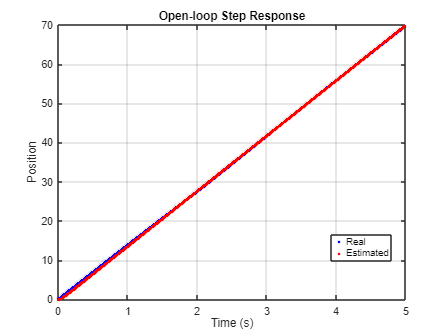


G =
 
       14.09
  ---------------
  0.03954 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 48.94%

G =
 
       14.09
  ---------------
  0.03954 s^2 + s
 
Continuous-time transfer function.


% Puntos para identificación
t1 = 2;  % Primer punto para identificación
t2 = 4.9;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,1)*180/pi, time.Data, t1, t2)

% G =
% 
%        14.09
%   ---------------
%   0.03954 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 48.94%


## Motor 2

joint1_only = 0;
joint2_only = 150;
joint3_only = 0;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

% Puntos para identificación
t1 = 2  % Primer punto para identificación
t2 = 4.9;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,2)*180/pi-90, time.Data, t1, t2)


% G =
% 
%        32.8
%   --------------
%   0.2307 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 591.36%


## Motor 3

joint1_only = 60;
joint2_only = 150;
joint3_only = 70;
joint4_only = 0;
joint5_only = 0;
joint6_only = 0;

% Puntos para identificación
t1 = 2  % Primer punto para identificación
t2 = 4;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,3)*180/pi-90, time.Data, t1, t2)


% G =
% 
%        29.85
%   ----------------
%   0.001451 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 706.38%

## Motor 4

joint1_only = 60;
joint2_only = 150;
joint3_only = 70;
joint4_only = 50;
joint5_only = 0;
joint6_only = 0;

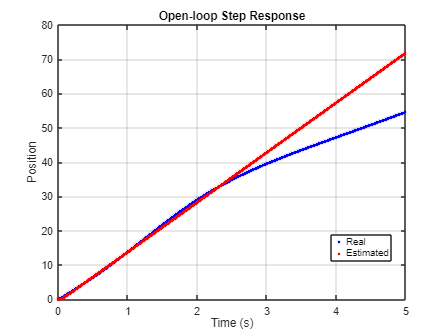


G =
 
       14.5
  ---------------
  0.04741 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 1555.75%

G =
 
       14.5
  ---------------
  0.04741 s^2 + s
 
Continuous-time transfer function.


% Puntos para identificación
t1 = 0;  % Primer punto para identificación
t2 = 2;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,4)*180/pi, time.Data, t1, t2)

% Considerando valores de 0:-50
% G =
% 
%       -10.06
%   --------------
%   0.3432 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: -626.43%

% Considerando valores de 0:50
% G =
% 
%        14.5
%   ---------------
%   0.04741 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 1555.75%

## Motor 5

joint1_only = 60;
joint2_only = 150;
joint3_only = 70;
joint4_only = 50;
joint5_only = 60;
joint6_only = 0;

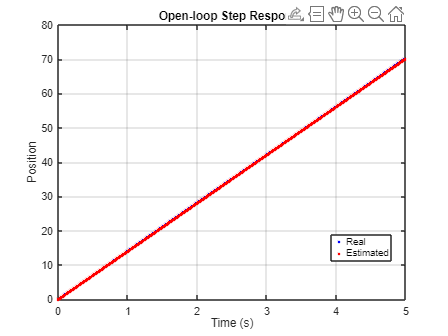


G =
 
        14.02
  -----------------
  0.0003768 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 13.23%

G =
 
        14.02
  -----------------
  0.0003768 s^2 + s
 
Continuous-time transfer function.


% Puntos para identificación
t1 = 2;  % Primer punto para identificación
t2 = 4.5;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,5)*180/pi, time.Data, t1, t2)

% G =
% 
%         14.02
%   -----------------
%   0.0003768 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 13.23%

## Motor 6

joint1_only = 60;
joint2_only = 150;
joint3_only = 70;
joint4_only = 50;
joint5_only = 60;
joint6_only = 40;

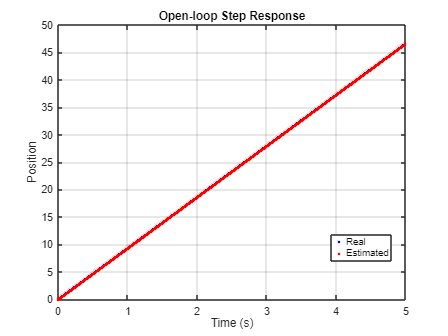


G =
 
        9.31
  ----------------
  0.001593 s^2 + s
 
Continuous-time transfer function.
Model Properties
Estimated transfer function:
Estimation error: 6.00%

G =
 
        9.31
  ----------------
  0.001593 s^2 + s
 
Continuous-time transfer function.


% Puntos para identificación
t1 = 2;  % Primer punto para identificación
t2 = 4.5;  % Segundo punto para identificación

% Identificar el sistema
G = identify_position_TF(Ts_identi, position(:,6)*180/pi, time.Data, t1, t2)

% G =
% 
%         9.31
%   ----------------
%   0.001593 s^2 + s
% 
% Continuous-time transfer function.
% Model Properties
% Estimated transfer function:
% Estimation error: 6.00%